% 批量读取文件夹内文件数据，并绘制相应的曲线图
clear;

% 获取所有绘图所用的资源数据
% Folder = "E:/MatlabWorkStation/temperatureprogressionexperiment/";  % 文件夹路径
Folder = "D:/EDProgram/MatlabForHeater/Compare/";
Files = dir(Folder);                % 获取文件夹路径下文件，结构体类型
Files = Files(~[Files.isdir]);      % 去掉本身和父文件夹，剩余的即为文件个数
FilesNum = length(Files);           % 获取文件个数
DataCell = cell(1,FilesNum);        % 创建文件数据存储元胞
XCell = cell(1,FilesNum);           % 创建 X 轴长度存储元胞=   
namestr = strings([1, FilesNum]);   % 字典 key 值字符串缓存数组
pidcell = cell(1,FilesNum);        % 字典 values 值缓存元胞
pidbuff = strings([7, 3]);         % 预设 PID 参数字符串缓存数组    
TableColumnNames = {'pt1','pt2','pt3','pt4','pt5','pt6','pt7',...               % table 表名
                    'pst1','pst2','pst3','pst4','pst5','pst6','pst7',...        
                    'pp1','pp2','pp3','pp4','pp5','pp6','pp7'};                 
% 轮询文件夹下所有文件
for i = 1:FilesNum
    str = string(strsplit(Files(i).name,'_'));
    %提取单个文件中七个点的 PID 参数
    for p_i = 1:7
        for p_j = 3:-1:1
            pidbuff(p_i,(4 - p_j)) = str(p_i*3 - p_j + 2);
        end
    end
    % 获取文件路径，读取文件中数据，重命名 table 表头
    Filename = fullfile(Folder, Files(i).name);
    DataCell{i} = readtable(Filename);
    DataCell{i}.Properties.VariableNames = TableColumnNames;
    % 获取 X 轴数据绘制长度
    XCell{i} = linspace(1,height(DataCell{i}),height(DataCell{i}));
    % 获取创建字典所需要的 keys 和 values
    namestr{i} = str{1};
    pidcell{i} = pidbuff;

%     if "temp150" == str(1)
%         for f_i = 1:1:7
%             figure(((i-1) * 7) + f_i);
%             plot(X,table2array(DataCell{i}(:,f_i)), ...
%                 "DisplayName",sprintf("Point=%d P=%s I=%s D=%s",f_i,parabuff(f_i,1),parabuff(f_i,2),parabuff(f_i,3)));
%             hold on;
%             plot(X,table2array(DataCell{i}(:,f_i + 7)), ...
%                  "DisplayName",sprintf("SetTemp: %s",extractAfter(str(1),"temp")));
%             set(gca,'Box','off', ...                                % 边框开关
%                 'LineWidth',1, ...                                  % 线宽（非数据线）
%                 'XGrid','off','YGrid','on', ...                     % 网格开关
%                 'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
%                 'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
%                 'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
%             hold off;
%             legend;
%         end
%     end
end
% 创建 PID 参数字典
piddic = dictionary(namestr,pidcell);

% 加载颜色集
run("Color.m");

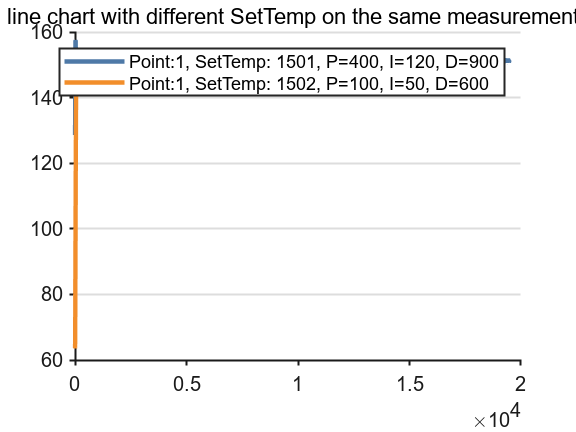

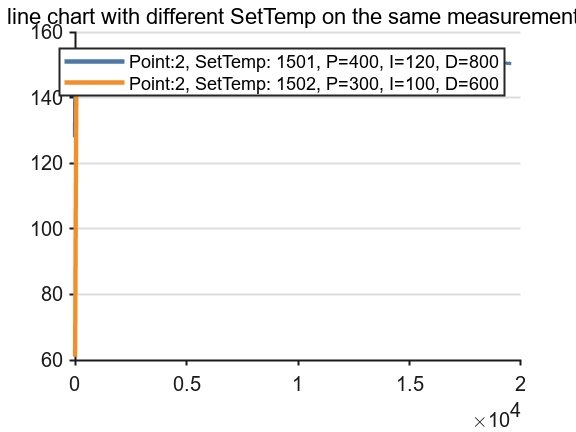

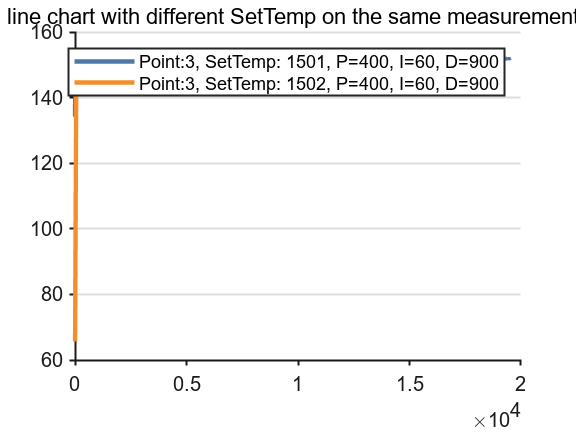

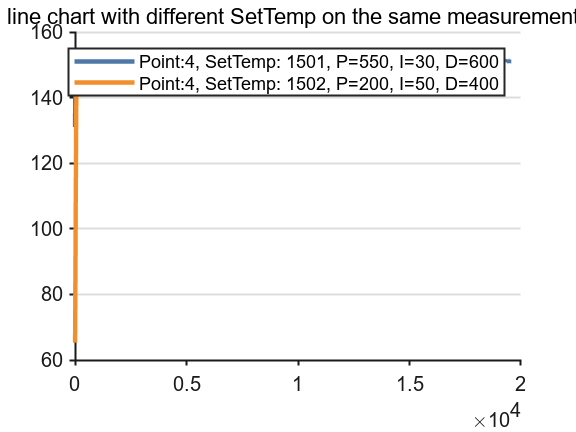

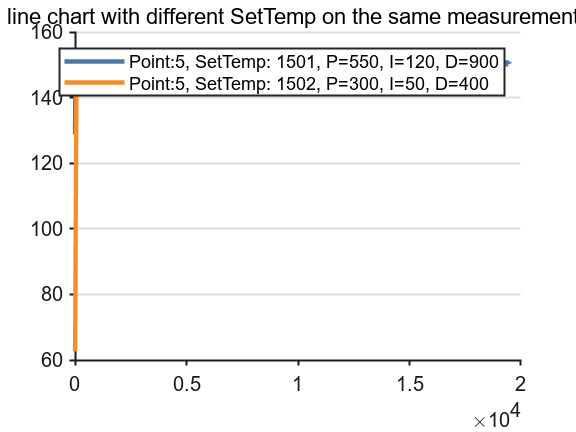

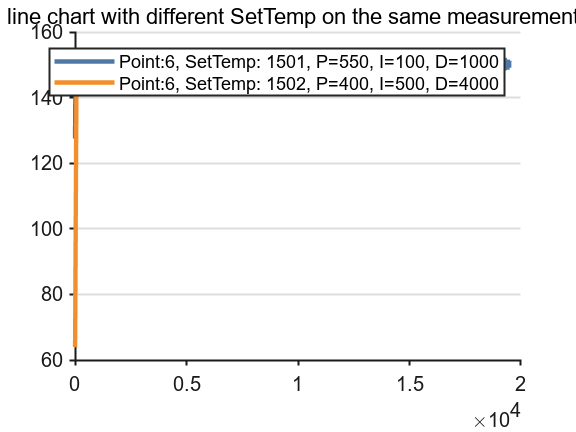

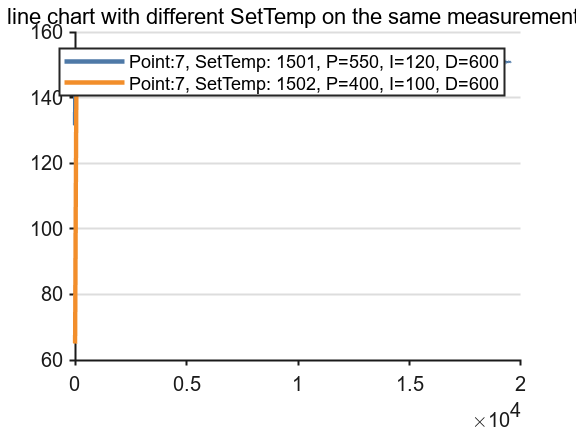

% 绘制各个数据文件中共同测温点的曲线图
close all;
for i = 1:1:7
%     subplot(4,2,i);
    figure;
    for j = 1:1:FilesNum
        pidcellbuffer = piddic(namestr{j});
        plot(XCell{j},table2array(DataCell{j}(:,i)), ...
             "DisplayName",sprintf("Point:%d, SetTemp: %s, P=%s, I=%s, D=%s",i,extractAfter(namestr{j},"temp"),pidcellbuffer{1}(i,1),pidcellbuffer{1}(i,2),pidcellbuffer{1}(i,3)), ...
             "LineWidth",2.2);
        hold on
    end
    set(gca,'Box','off', ...                                % 边框开关
        'LineWidth',1, ...                                  % 线宽（非数据线）
        'XGrid','off','YGrid','on', ...                     % 网格开关
        'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
        'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
        'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
    legend;
    colororder(color1002);
    title("PID line chart with different SetTemp on the same measurement point");
    hold off;
end

% 绘制各个数据文件中七个测温点的曲线图
close all;
for i = 1:1:FilesNum
    figure(i);
    for j = 1:1:7
        pidcellbuffer = piddic(namestr{i});
        plot(XCell{i},table2array(DataCell{i}(:,j)), ...
             "DisplayName",sprintf("Point: %d, P=%s, I=%s, D=%s",j,pidcellbuffer{1}(j,1),pidcellbuffer{1}(j,2),pidcellbuffer{1}(j,3)), ...
             "LineWidth",2.2);
        hold on
    end
    set(gca,'Box','off', ...                                % 边框开关
        'LineWidth',1, ...                                  % 线宽（非数据线）
        'XGrid','off','YGrid','on', ...                     % 网格开关
        'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
        'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
        'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
    legend;
    colororder(color1002);
    title(sprintf("PID line chart. SetTemp: %s",extractAfter(namestr{i},"temp")));
    hold off;
end

